# Mechanical Systems Modeling & Simulation Using Simulink (Using Mathematical Equations which is Much Harder Compared to Physics-based Modeling in SimScape!)

## Part 1: 1-DOF Translational Mechanical System

## Task #1. Understand the Project Scope 

System modeling is used to map the reality (real dynamic system such as a car) into a set of simplified mathematical equations (model).

A system model is a set of governing mathematical equations which describe the model's dynamical behavior.

Once you have a governing mathematical equations, you can then simulate the system and assess its performance using simulation tools such as Matlab/Simulink.

As a rule of thumb, we keep the model simple at first and add complexity as needed later on!

The dynamics of many systems, whether they are mechanical, electrical, thermal, economic, etc., may be described in terms of differential equations. Such differential equations may be obtained by using physical laws such as Newton's laws for mechanical systems or Kirchhoff's laws for electrical systems. 

Consider a simple mass spring damper system as shown below:

               Assume M = 1 Kg, b = 1 Ns/m, k =1 N/m

                                                                             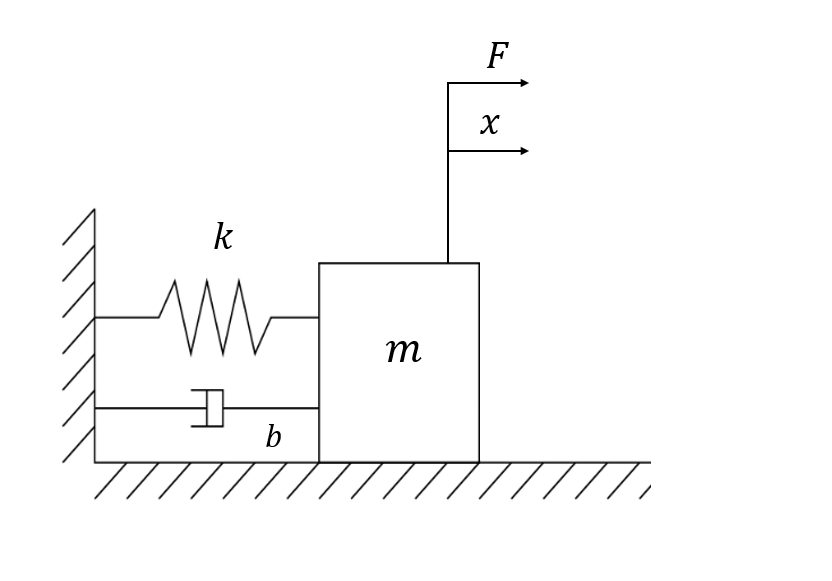

## Task #2: Draw the Free Body Diagram & Derive Mathematical Equations

Let's draw the free body diagram of the system, The Force F is the input to the system and displacement x is the output.

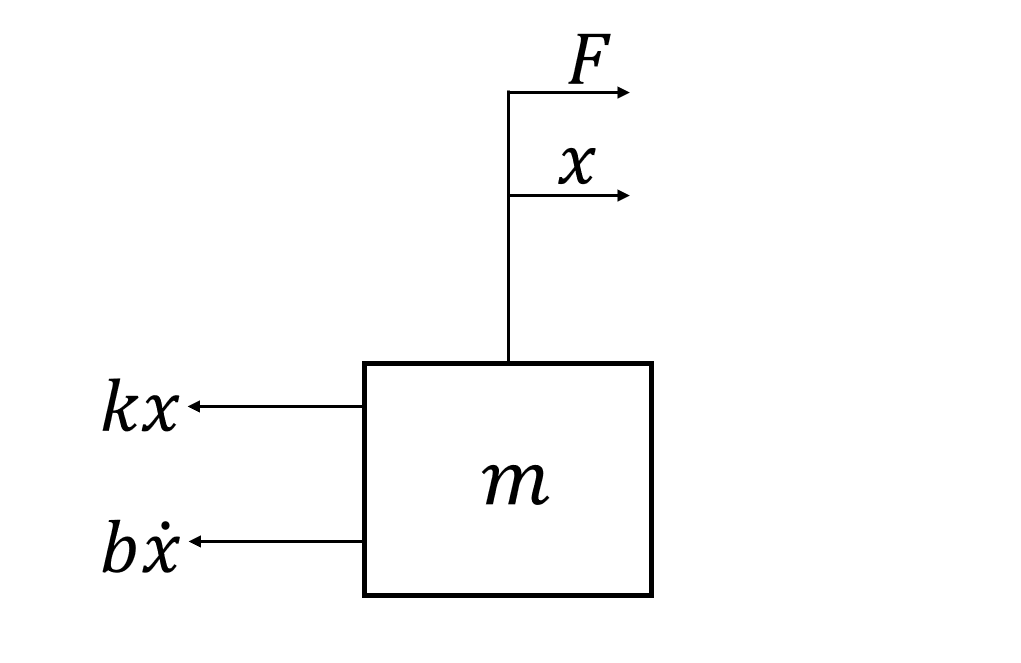

The spring force is directly proportianal to the displacement $x$ while the viscous damping force is directly proportional to the velocity $\dot{x}$.

Using Newton's Second law of motion, the system can be described by the following equations:

                                                                    
$$M\ddot{x} =F-b\dot{x} -\textrm{kx}$$


                                                                  
$$ẍ=1/M\left(F-\textrm{bx}̇-\textrm{kx}\right)$$



$$$$


## Task #3. Build Simulink Model 

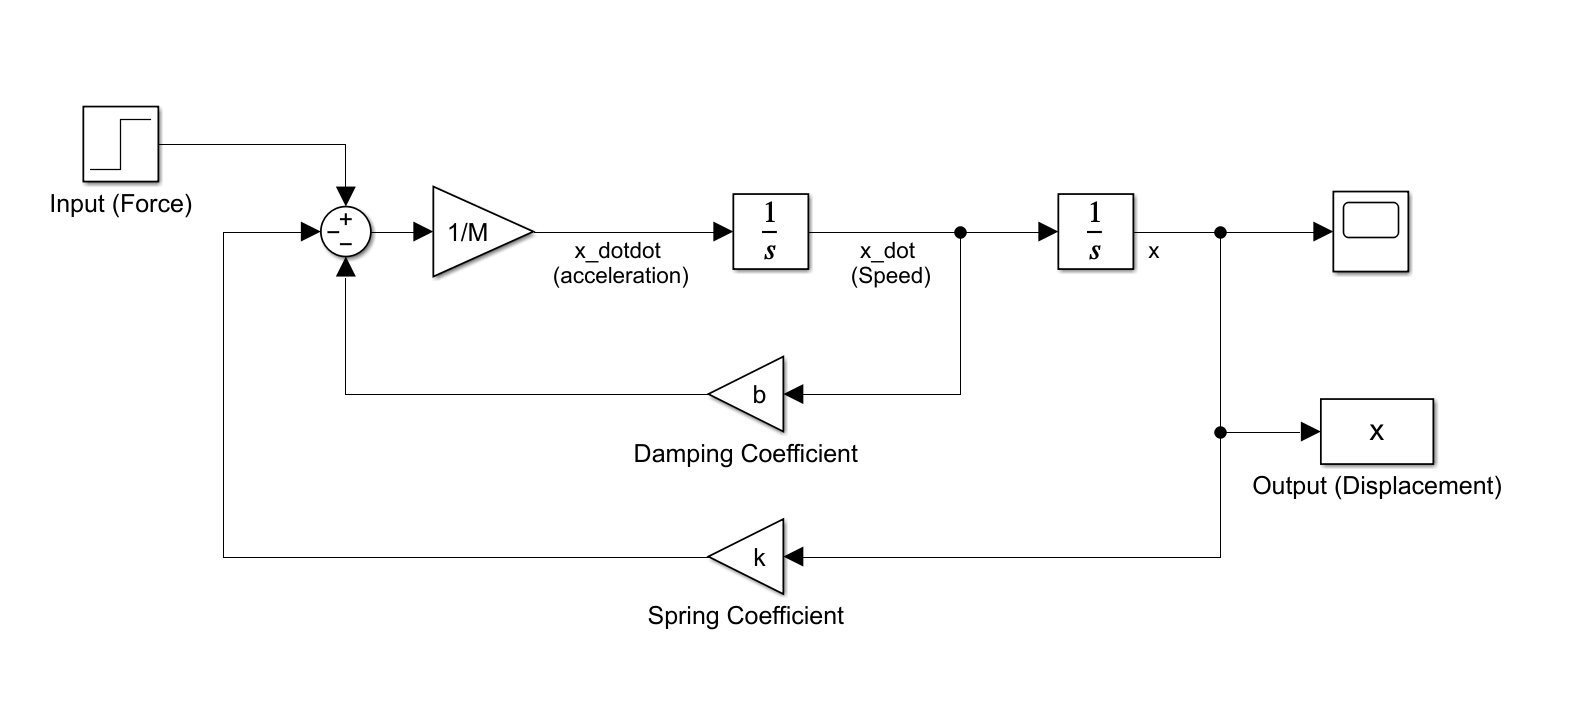

## Task #4: Simulate the Model

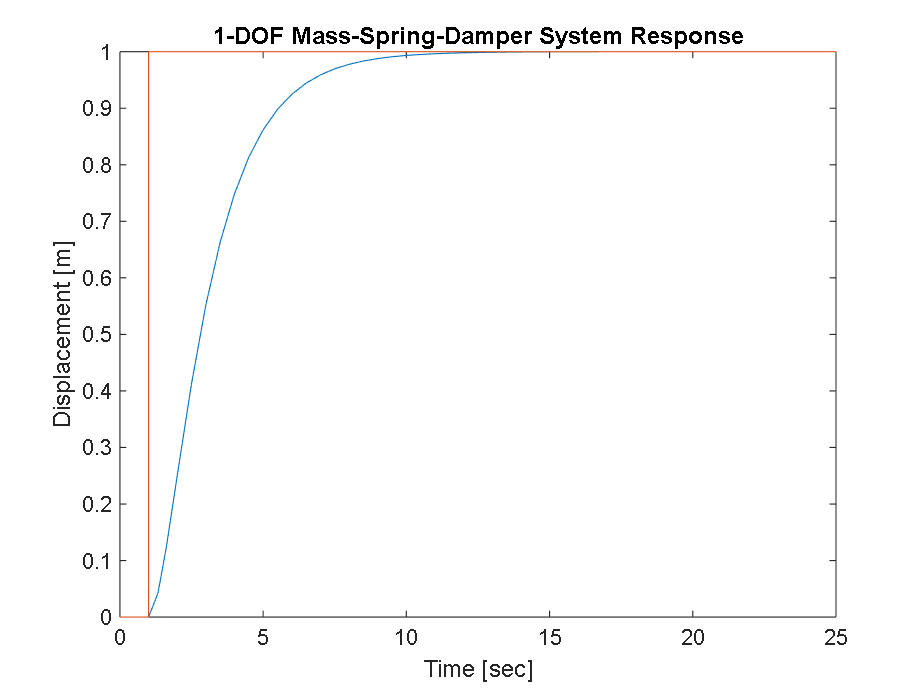

% Define Model Parameters
Sim_Time = 25;
F = 1;
M = 1;
b = 2.25;
k = 1;
sim('mass_spring_damper_simulink.slx'); %connect to the simulink
figure %for figure plotting of the model
plot(ans.x) %for plotting x output
hold on %for saving the plot in real-time
plot(ans.F) %for plotting F input
hold on
ylabel('Displacement [m]')
xlabel('Time [sec]')
title('1-DOF Mass-Spring-Damper System Response')

## Part 2: 2-DOF Translational Mechanical System

In this final end of day project, please complete the following tasks: 

- Draw the free body diagram for the following system.

- Build a two degrees of freedom mechanical system using Simulink as shown below. 

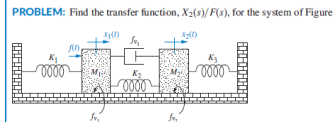

        3. Assuming m1 = 1 Kg, fv1 = 1 Ns/m, k1 = 1 N/m, m2 = 1 Kg, fv2 = 1 Ns/m, k2 = 1 N/m, fv3 = 1 Ns/m, k3 = 1 M/m apply a unit step input F and simulate the system. 

        4. Plot the displacement x1, x2, and Force (input) on one graph.

        5. Assume that the system has no damping element, simulate the system and comment on the results. 

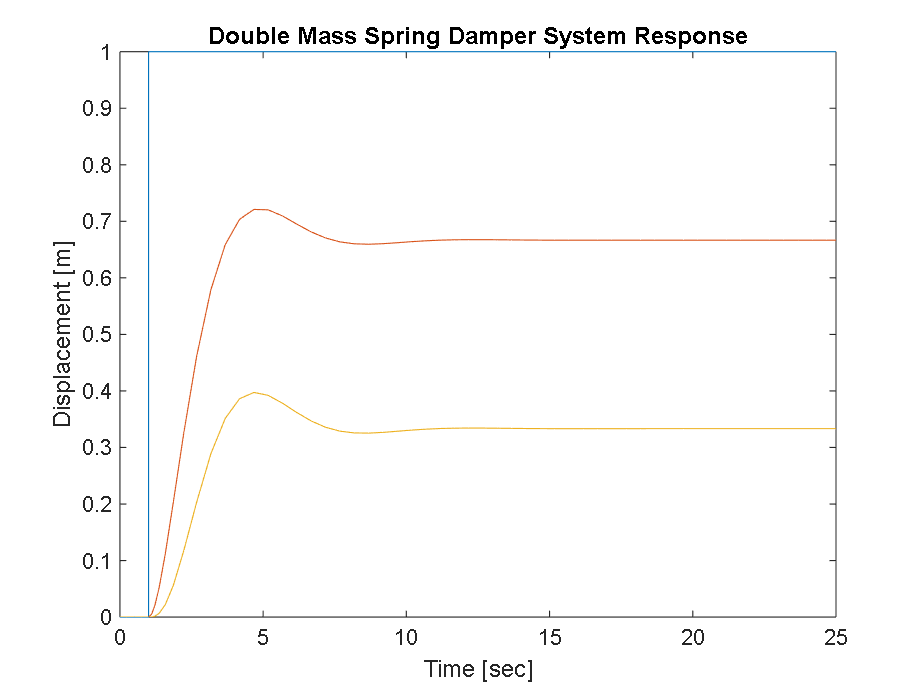

% Define Model Parameters
Sim_Time1 = 25;
F1 = 1;
M1 = 1;
fv1 =1.2;
k1 = 1;

M2 = 1;
fv2 =1;
k2 = 1;

fv3 =1.1;
k3 = 1;

sim('two_DOF_Translational_system.slx');
figure
plot(ans.F1)
hold on 
plot(ans.x1)
hold on 
plot(ans.x2)
ylabel('Displacement [m]')
xlabel('Time [sec]')
title('Double Mass Spring Damper System Response')